# ** OFDM Receiver Using Software Defined Radio**

This example shows how to design an orthogonal frequency division multiplexing (OFDM) receiver for a single-input single-output (SISO) channel using a software-defined radio (SDR). The OFDM receiver captures and demodulates the OFDM signal that the [OFDM Transmitter Using Software-Defined Radio](docid:usrpradio_ug#mw_5b3bfbe2-c85e-4cd6-9760-4a3700138d6b) example sends. The OFDM receiver design includes sample buffering for timing adjustment, filtering, carrier frequency adjustment, and OFDM demodulation.

## Required Hardware and Software

To run this example, you need one of these SDRs and the corresponding software support package.

- USRP™ N2xx or B2xx series radio and [Communications Toolbox Support Package for USRP Radio](https://www.mathworks.com/hardware-support/usrp.html). For information on supported radios, see [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1).

- USRP E3xx, N3xx, X3xx, or X4xx series radio and [Wireless Testbench Support Package for NI USRP Radios](https://www.mathworks.com/hardware-support/ni-usrp-radios.html). For information on supported radios, see [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002).

- ADALM-PLUTO radio and the Communications Toolbox Support Package for Analog Devices® ADALM-PLUTO Radio. 

The example requires two MATLAB™ sessions, one for the transmitter and one for the receiver. You run the OFDM Transmitter Using Software-Defined Radio example in one MATLAB session to transmit the OFDM signal.

## Set OFDM Frame Parameters

Set the OFDM parameters, including the FFT length, cyclic prefix length, and number of subcarriers. The pilot subcarrier spacing and channel bandwidth are fixed at 30 KHz and 3 MHz, respectively.

After configuring the OFDM parameters, set the data parameters. Set the modulation order, code rate, number of symbols per frame, and the number of frames per transmission. 

You can enable or disable the scopes for visualization, however for long simulations, it is recommended to disable the scope. To control the display of the diagnostic output text, enable or disable the verbosity as needed. To view the decoded data in each frame, enable the print data flag

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 90;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 30e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e6;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 4;   % Data modulation order
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame
dataParams.numFrames      = 2000;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = false;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data

## Initialize Receiver Parameters

The `helperGetRadioParams` function initializes the receiver System object™  `ofdmRx`. Assign the name of the radio you are using for receiving the OFDM signal to the variable `radioDevice`. Set the receiver gain and operating center frequency.

The `helperGetRadioRxObj` function initializes the radio receiver System object.

radioDevice            = "PLUTO";   % Choose radio device for reception
centerFrequency        = 3e9;   % Center Frequency
gain                   = 10;   % Set radio gain

The `helperOFDMSetParamsSDR` function initializes transmit-specific and common transmitter and receiver parameters required for the OFDM simulation and the `helperGetRadioParams` function initializes the parameters required for the receiver System object™ radio.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

 % 
 % ofdmRx                   = sdrrx('Pluto', ...
 %    'RadioID', 'usb:1', ...
 %    'CenterFrequency', centerFrequency, ...
 %    'BasebandSampleRate', sampleRate, ...
 %    "SamplesPerFrame", 32768, ...
 %    'OutputDataType', 'double', ...
 %    'GainSource', 'AGC Fast Attack');





 % 1. Define the Serial Number for the Receiver
targetSerialRx = '1044739a470b0002ffff270027b37feec0'; 

% 2. Find all connected Plutos
radios = findPlutoRadio;
rxRadioID = '';

% 3. Loop through them to find the match
for i = 1:length(radios)
    if strcmp(radios(i).SerialNum, targetSerialRx)
        rxRadioID = radios(i).RadioID; % Grab the correct 'usb:X' ID
        break;
    end
end

% 4. Error check: Did we find it?
if isempty(rxRadioID)
    error('Receiver Pluto not found! Check connection.');
end

disp(['Receiver successfully connected to: ' rxRadioID]);

Receiver successfully connected to: usb:0



% 5. Initialize the Receiver using the found ID
ofdmRx = sdrrx('Pluto', ...
    'RadioID', rxRadioID, ... 
    'CenterFrequency', centerFrequency, ...
    'BasebandSampleRate', sampleRate, ...
    'SamplesPerFrame', 32768, ...
    'OutputDataType', 'double', ...
    'GainSource', 'AGC Fast Attack');

## Execute Receiver Loop

#### Synchronization

The OFDM receiver checks the sample buffer for the synchronization symbol to find the starting point of the data frames within the received OFDM signal. The receiver correlated the received OFDM signal with the known synchronization symbol. Once the OFDM receiver detects a high correlation peak, it identifies the position where it finds the synchronization symbol as the start of the frame.  

#### Frequency Offset Estimation and Correction

The OFDM receiver estimates and corrects the frequency and timing offset introduced to the transmitted OFDM signal due to channel impairments. The OFDM receiver checks the receiver buffer for the required number of frames and performs automatic frequency correction over each symbol. The receiver averages the frequency correction across the subcarriers and then across every six symbols, considering a group of six symbols as a slot. The receiver considers the overall average value of these corrections as the frequency offset and compensates this frequency offset across the entire frame.

The receiver is considered camped to a based station upon achieving successful synchronization and channel impairment correction. 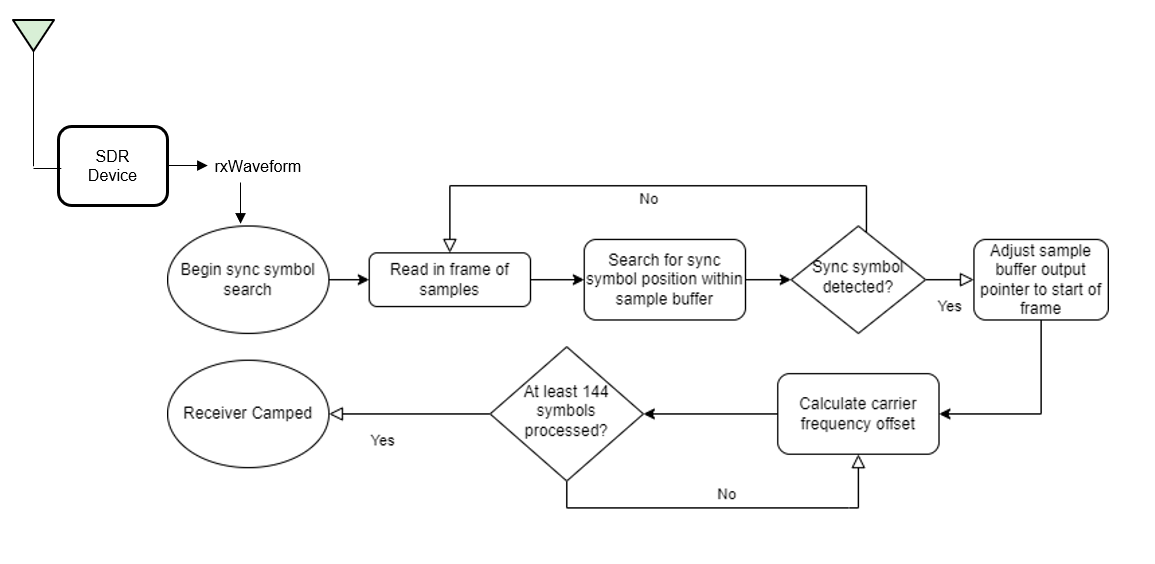

### Receiver Processing

This process is the reverse of the process that happens at the transmitter.

#### Channel Estimation and Equalization

Initially, the OFDM receiver performs channel estimation on the OFDM demodulated reference symbols. To remove the effects of time-varying fading, the receiver selects two reference symbols from adjacent frames to estimate the channel at two different points in time. The receiver then linearly interpolates the channel estimates between the two reference symbols to get the channel estimates for the header and data symbols. The `ofdmEqualize` function then equalizes the reference symbols and data symbols using the channel estimates.

#### Header Decoding

The receiver extracts and decodes the header symbols to get the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The receiver uses these parameters to demodulate and decode the data symbols.

#### Data Decoding

The common phase error (CPE) affects all subcarriers equally and the OFDM receiver uses the pilot symbols within the data symbols to estimate CPE. The `helperOFDMRx` function corrects the phase errors in the data symbols and the `qamdemod` function soft decodes the data subcarriers into log likelihood ratios (LLRs).

The receiver then deinterleaves the demodulated bitstream and the `vitdec` function performs maximum likelihood decoding using the Viterbi algorithm. The descrambler descrambles the decoded bits, and the `comm.CRCDetector` computes the cyclic redundancy check (CRC) and compares it with the appended CRC.

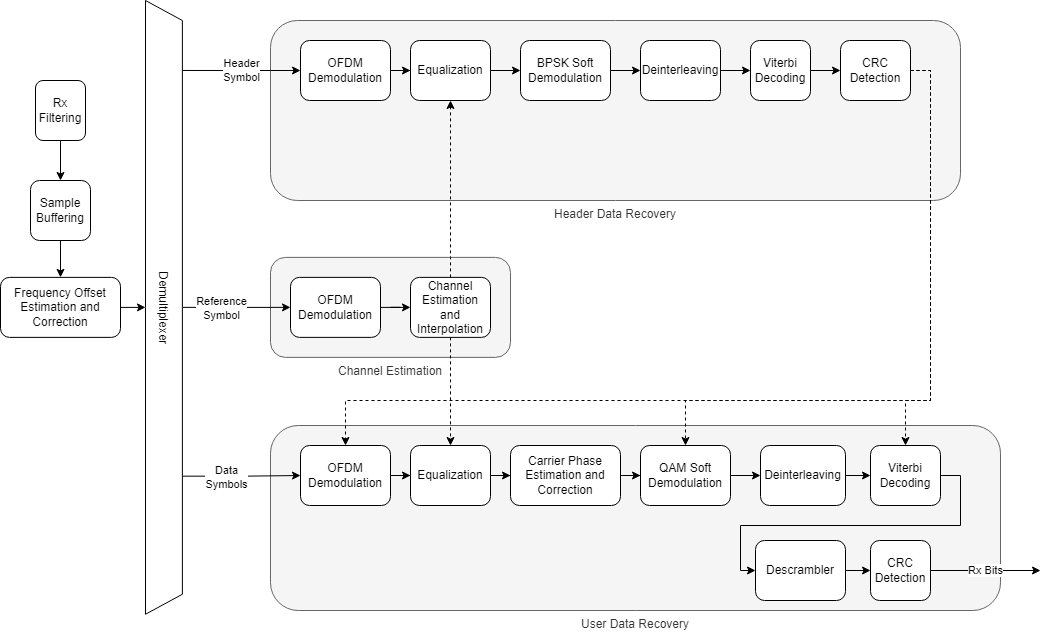

% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

errorRate = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER = zeros(1,dataParams.numFrames);
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio();

    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data up to last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end

## Establishing connection to hardware. This process can take several seconds.



Sync symbol found.
Estimating carrier frequency offset ........
Receiver camped.
.

Received data in frame 9: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 10: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 11: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 12: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 13: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 14: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 15: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 16: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 17: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 18: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 19: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 20: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 21: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 22: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 23: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 24: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 25: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 26: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 27: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 28: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 29: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 30: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 31: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 32: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 33: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 34: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 35: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 36: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 37: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 38: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 39: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 40: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 41: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 42: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 43: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 44: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 45: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 46: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 47: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 48: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 49: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 50: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 51: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 52: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 53: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 54: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 55: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 56: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 57: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 58: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 59: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 60: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 61: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 62: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 63: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 64: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 65: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 66: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 67: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 68: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 69: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 70: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 71: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 72: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 73: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 74: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 75: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 76: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 77: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 78: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 79: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 80: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 81: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 82: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 83: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 84: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 85: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 86: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 87: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 88: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 89: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 90: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 91: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 92: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 93: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 94: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 95: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 96: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 97: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 98: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 99: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 100: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 101: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 102: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 103: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 104: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 105: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 106: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 107: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 108: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 109: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 110: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 111: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 112: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 113: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 114: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 115: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 116: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 117: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 118: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 119: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 120: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 121: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 122: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 123: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 124: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 125: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 126: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 127: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 128: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 129: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 130: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 131: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 132: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 133: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 134: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 135: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 136: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 137: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 138: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 139: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 140: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 141: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 142: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 143: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 144: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 145: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 146: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 147: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 148: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 149: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 150: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 151: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 152: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 153: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 154: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 155: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 156: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 157: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 158: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 159: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 160: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 161: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 162: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 163: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 164: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 165: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 166: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 167: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 168: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 169: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 170: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 171: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 172: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 173: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 174: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 175: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 176: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 177: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 178: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 179: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 180: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 181: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 182: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 183: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 184: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 185: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 186: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 187: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 188: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 189: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 190: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 191: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 192: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 193: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 194: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 195: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 196: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 197: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 198: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 199: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 200: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 201: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 202: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 203: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 204: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 205: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 206: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 207: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 208: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 209: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 210: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 211: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 212: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 213: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 214: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 215: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 216: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 217: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 218: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 219: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 220: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 221: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 222: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 223: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 224: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 225: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 226: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 227: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 228: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 229: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 230: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 231: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 232: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 233: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 234: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 235: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 236: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 237: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 238: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 239: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 240: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 241: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 242: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 243: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 244: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 245: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 246: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 247: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 248: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 249: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 250: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 251: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 252: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 253: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 254: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 255: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 256: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 257: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 258: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 259: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 260: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 261: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 262: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 263: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 264: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 265: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 266: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 267: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 268: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 269: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 270: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 271: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 272: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 273: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 274: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 275: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 276: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 277: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 278: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 279: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 280: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 281: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 282: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 283: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 284: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 285: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 286: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 287: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 288: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 289: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 290: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 291: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 292: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 293: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 294: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 295: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 296: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 297: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 298: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 299: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 300: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 301: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 302: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 303: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 304: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 305: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 306: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 307: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 308: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 309: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 310: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 311: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 312: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 313: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 314: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 315: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 316: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 317: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 318: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 319: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 320: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 321: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 322: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 323: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 324: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 325: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 326: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 327: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 328: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 329: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 330: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 331: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 332: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 333: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 334: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 335: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 336: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 337: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 338: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 339: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 340: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 341: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 342: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 343: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 344: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 345: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 346: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 347: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 348: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 349: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 350: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 351: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 352: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 353: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 354: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 355: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 356: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 357: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 358: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 359: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 360: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 361: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 362: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 363: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 364: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 365: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 366: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 367: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 368: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 369: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 370: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 371: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 372: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 373: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 374: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 375: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 376: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 377: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 378: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 379: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 380: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 381: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 382: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 383: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 384: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 385: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 386: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 387: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 388: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 389: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 390: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 391: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 392: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 393: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 394: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 395: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 396: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 397: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 398: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 399: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.


Received data in frame 400: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 401: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 402: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 403: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 404: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 405: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 406: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 407: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 408: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

.

Received data in frame 409: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hell

% Display the mean BER value across all frames
fprintf('Simulation complete!\nAverage BER = %d',mean(BER))
release(radio);

## Troubleshooting

#### **No data in any frame**

Problem

- The receiver continuously receives no data in any frame.

Possible causes

- Transmitter is not running

- Too high or too low transmitter and receiver gains

- Too many under-runs at the transmitter

Possible solutions

- Ensure that the transmitter is running

- Adjust the transmitter and receiver gains

- Adjust the frame length to make sure there are very few under-runs at the transmitter.

#### **Header CRC fails**

Problem

- Even when synchronization and receiver camping are successful, the header CRC check fails.

Possible causes

-  Insufficient compensation of clock frequency offset.

Possible solutions

- The frequency compensation algorithm measures and corrects the frequency and phase offset for each frame, and it can estimate the correct offset up to half of the subcarrier spacing. You can calibrate the frequency offset to resolve this error.

For USRP radios, you can determine the frequency offset by sending a tone at a known frequency from the transmitter and measure the offset between the transmitted and received frequency. Apply the measured offset to the center frequency of `comm.SDRuReceiver` receiver System object.

For ADALM-Pluto radios, run the [Frequency offset calibration with ADALM-Pluto Radio in Simulink](docid:plutoradio_ug#mw_baa863fb-d239-4495-baf9-eb6864e0f592) example to get the frequency offset. Apply the measured offset to the center frequency of the `comm.SDRRxPluto`  receiver System object.

#### **Data decoding fails**

Problem

- The data decoding fails even when the header CRC decoding is successful.

Possible causes

- Data overflow at the receiver

- Inaccurate channel estimate due to exceeding frame length.

Possible solutions

-  Adjust the frame size

- Change the number of symbols per frame to minimize the frame length.

## Further Exploration

You can use an external clock source or GPSDO with the radios to try smaller subcarrier spacing of 15 KHz with smaller bandwidths such as 1.4 MHz (LTE bandwidths) or higher FFTLengths such as 256. 

This example uses burst mode in the radios to receive the data, with the burst size set to the number of frames. You can further explore receiving the data using the radios in non-burst mode.

*Copyright 2023-2025 The MathWorks, Inc.*